clc; clear all; close all;

img_path = fullfile('Codes','fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

RGB = imread(string(fullfile(img_path, T{265,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
maxR=max(R(:));
maxG=max(G(:));
maxB=max(B(:)); 

figure;

imshow((RGB));

figure;

imshow(RGB(:,:,1),[0.9*maxR maxR]);

figure;

imshow(RGB(:,:,2),[0*maxG maxG]);

figure;

imshow(RGB(:,:,3),[0*maxB maxB]);

The region of interest, which is the neighborhood of the optic disk, has been extracted from the original fundus image.

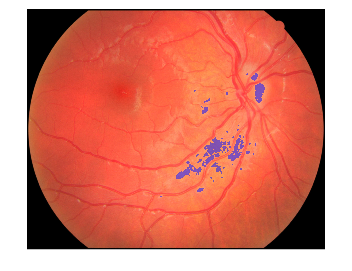

Ig=rgb2gray(RGB);
%Seleccionamos el 10% más lulminoso de la imagen
max_Ig=max(Ig(:));
two_perc=Ig>=0.85*max_Ig;%si lo subes demasiado en algunas imagenes no da (P.e. la 857) pero si lo bajas demasiado otras no dan (P.e. la 39)

%Antes de hacer la clasificación en grupos hay que hacer un opening porque
%si no te van a dar un montón de grupos
se = strel('disk',6);%Se hace el opening con un disk (Forma redonda) del tamaño que elijas
afterOpening = imopen(two_perc,se);

%Se ha conseguido esto:
segI=labeloverlay(RGB,afterOpening);
figure;
imshow(segI);

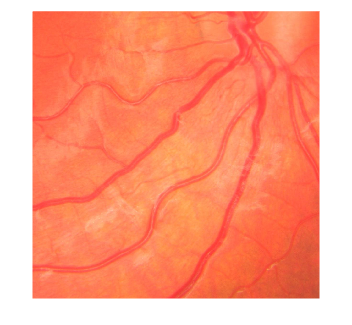


%Clasificamos los grupos que se han conseguido
grupos_matriz = bwlabel(afterOpening,4);
grupos = unique(grupos_matriz);% Uno de los grupos es el fondo

%Cual de los grupos ocupa más píxeles? Ese será parte del OD
conteo = histc(grupos_matriz(:), grupos);
[~, idx_ordenado] = sort(conteo, 'descend');%Esto ordena del mayor grupo al menor
grupo_mas_repetido = grupos(idx_ordenado(2));%este es el grupo del OD, se pone como el segundo grupo más grande porque el primero es el fondo
OD_location_muestra=grupos_matriz==grupo_mas_repetido;

[row, col] = find(OD_location_muestra);%Busca los elementos no 0

% Calcula el centroide
centroideX = round(mean(col)); %lo redondeo porque lo que quiero es la posición de un pixel, tiene que ser integer
centroideY = round(mean(row));

% Recortamos el OD de la imagen original, utilizamos el centroide de la muestra y un margen establecido
margen=600;

%Le pongo el if por si el marco se sale de la imagen, para que no de error
if centroideY+margen>height(RGB)
   centroideY=height(RGB)-margen;
elseif centroideY-margen<1
    centroideY=margen+1;
end

if centroideX+margen>width(RGB)
   centroideX=width(RGB)-margen;
elseif centroideX-margen<1
    centroideX=margen+1;
end
   

OD_zoomR = R(centroideY-margen:centroideY+margen, centroideX-margen:centroideX+margen);
OD_zoomG = G(centroideY-margen:centroideY+margen, centroideX-margen:centroideX+margen);
OD_zoomB = B(centroideY-margen:centroideY+margen, centroideX-margen:centroideX+margen);
OD_zoomRGB = cat(3, OD_zoomR, OD_zoomG, OD_zoomB);%Para juntar las 3 layers


% Mostramos lo que hemos conseguido:
figure;
imshow(OD_zoomRGB);


Ig=rgb2gray(OD_zoomRGB);

Código para saber si es ojo derecho o izquierdo (esta info se va a usar mucho más adelante)

La cabeza del nervio optico está en el lado nasal, por lo tanto, si en la retinografía se encuentra a la derecha, se va a tratar del ojo derecho, y si está a la izquierda corresponderá al ojo izquierdo.

**En imágenes como la 857 no hace bien porque está demasiado centrado!!**

medio_imagen=width(RGB)/2;
if centroideX<medio_imagen
    ojo='OI';
else
    ojo='OD';
end

Extracting the red channel from the original RBG images (OD_zoomRGB)

primero ploteo todas las layer para ver como sería y luego le extraigo la R layer

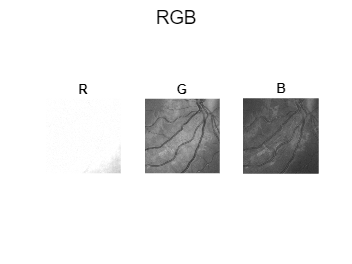

figure;
sgtitle('RGB')
subplot(1,3,1);
imshow(OD_zoomR)
title('R');
subplot(1,3,2);
imshow(OD_zoomG)
title('G');
subplot(1,3,3);
imshow(OD_zoomB)
title('B');

extraigo la R layer

OD_zoomGB=OD_zoomRGB;
OD_zoomGB(:,:,1)=0;

ploteo como queda la imagen solo con las layers G y B, las equalizo y les quito el ruido. Lo comparo con la layer R

figure;
sgtitle('R layer extraction')
subplot(3,2,1);
imshow(OD_zoomR);
title('R');
subplot(3,2,2);
imshow(rgb2gray(OD_zoomGB));
title('GB')

histogram equalization:

OD_zoomR_histeq=histeq(OD_zoomR);
OD_zoomGB_histeq=histeq(OD_zoomGB);
subplot(3,2,3);
imshow(OD_zoomR_histeq);
title('R eq');
subplot(3,2,4);
imshow(OD_zoomGB_histeq);
title('GB eq')

median filtering (considering 3x3 neighborhood window) has been performed for the removal of the noise

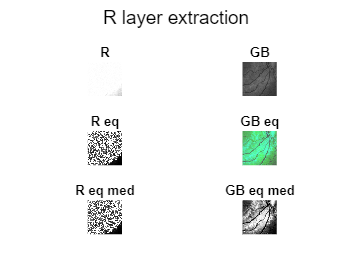

median_filteredR = medfilt2(histeq(OD_zoomR), [3 3]);
subplot(3,2,5);
imshow(histeq(median_filteredR));
title('R eq med');
OD_zoomGB_g=rgb2gray(histeq(OD_zoomGB));
median_filteredGB = medfilt2(OD_zoomGB_g, [3 3]);
subplot(3,2,6);
imshow(histeq(median_filteredGB));
title('GB eq med');

Aquí voy a improvisar cn cosas que creo que pueden funcionar (**H**igh **C**ontrast) No funciona en los casos en los que se ven cachos negros de fuera de la imagen

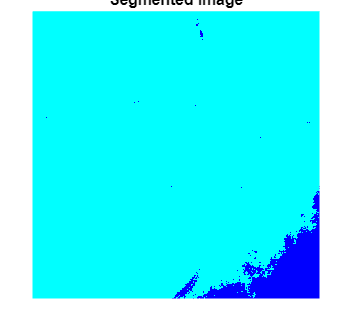

cuantas_hist_bins=max(OD_zoomR(:))-min(OD_zoomR(:));%el histograma no va de 0 a 255

[N,edges] = histcounts(OD_zoomR,cuantas_hist_bins);
minimos_relativos = islocalmin(N);
% Encontrar el índice del último mínimo relativo
ultimo_minimo_relativo = find(minimos_relativos, 1, 'last');

N_2a_mitad=N(end-30:end);
[minimo_pixeles, indice] = min(N_2a_mitad(:));
valor_pixel_menor_numero_pixeles = edges(ultimo_minimo_relativo);

labels = imquantize(OD_zoomR,valor_pixel_menor_numero_pixeles);
labelsRGB = label2rgb(labels);
figure;
imshow(labelsRGB)
title("Segmented Image")

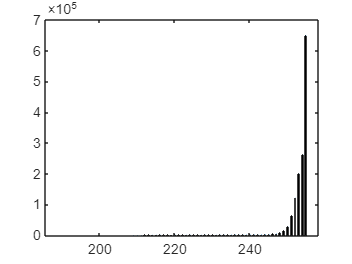


%Calculo el gradiente de la imagen
[Gx,Gy] = imgradientxy(OD_zoomR);
[Gmag,Gdir] = imgradient(Gx,Gy);
figure;
histogram(OD_zoomR);

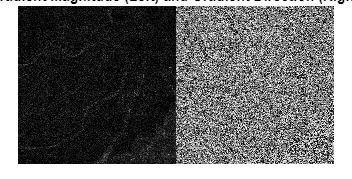

figure;
imshowpair(Gmag,Gdir,'montage');
title('Gradient Magnitude (Left) and Gradient Direction (Right)');

The literature suggests that the green channel of the original RGB image provides best prominence of the blood  vessels, whereas the red channel provides less contrast  between the background and edges of the vessel like  structures [7]. As in this work the focus has been given to  the optic disk segmentation, the red channel has been considered for fending off the blood vessels. **Canny to red channel creo**

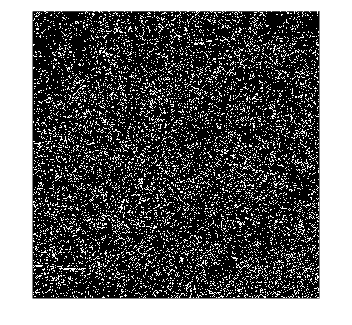

OD_zoomR_canny = edge(OD_zoomR, 'Canny');
figure;
imshow(OD_zoomR_canny);

The image has also been converted into the hue-saturation-value (HSV)  color model. It has been observed that the saturation and value channel has less prominence of blood vessels inside the optic disk.

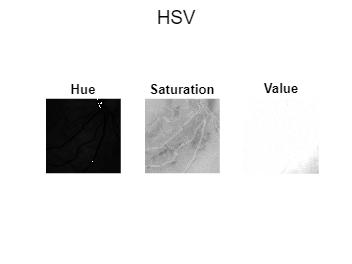

OD_zoomHSV=rgb2hsv(OD_zoomRGB);
figure;
sgtitle('HSV')
subplot(1,3,1);
imshow(OD_zoomHSV(:,:,1));
title('Hue');
subplot(1,3,2);
imshow(OD_zoomHSV(:,:,2));
title('Saturation');
subplot(1,3,3);
imshow(OD_zoomHSV(:,:,3));
title('Value')

The value channel of the HSV color model has high optic disk intensity. La saturación tb destaca en el optic disk.

OD_zoomS=OD_zoomHSV(:,:,2);
OD_zoomV=OD_zoomHSV(:,:,3);

Considering the advantages of different color channels, pixel by pixel multiplication has  been performed between the red, saturation and value channels of the fundus image **Me he quedado aquí**

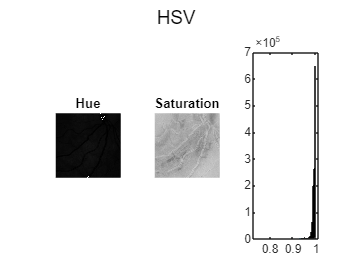

OD_zoomR_histeq=double(OD_zoomR_histeq);
umbral = 0.9;
OD_zoomV_thresholded = OD_zoomV>=0.85;
OD_zoom_mix=OD_zoomR_histeq.*(OD_zoomV_thresholded.^1);
histogram(OD_zoomV)

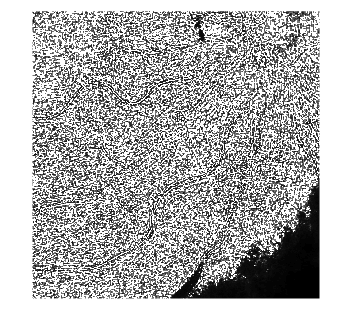

figure;
imshow(OD_zoomR_histeq,[]);

title('OD_zoomR_histeq')
figure;
imshow(OD_zoomV,[]);
title('OD_zoomV')

The modified resultant images have been shown **Mira bien cuales son las ertzas**

OD_zoom_mix=uint8(OD_zoom_mix);
figure;
bla=imshow(OD_zoom_mix,[]);
h = imdistline

se = strel('disk',10);
OD_zoom_mix_opened=imopen(OD_zoom_mix, se);
figure;
imshow(OD_zoom_mix_opened,[]);



%Clasificamos los grupos que se han conseguido
grupos_matriz = bwlabel(OD_zoom_mix_opened,4);
grupos = unique(grupos_matriz);% Uno de los grupos es el fondo

%Cual de los grupos ocupa más píxeles? Ese será parte del OD
conteo = histc(grupos_matriz(:), grupos);
[~, idx_ordenado] = sort(conteo, 'descend');%Esto ordena del mayor grupo al menor
grupo_mas_repetido = grupos(idx_ordenado(2));%este es el grupo del OD, se pone como el segundo grupo más grande porque el primero es el fondo
OD_pixels=grupos_matriz==grupo_mas_repetido;

%Se ha conseguido esto:
segI=labeloverlay(OD_zoomRGB,OD_pixels);
figure;
imshow(segI);

OD_pixels=double(OD_pixels);
OD_recortado=OD_zoomGB_g.*OD_pixels;
figure;
imshow(OD_recortado);

centroideY

From the resultant images it has  been observed that the contrast of optic disk region with  respect to the background has been enhanced and  simultaneously the vessel like objects have been suppressed.

B. Morphological Closing Operation

In this proposed work the morphological closing of the  image has been performed using a disk shaped structuring  element (SE). The intensity of the blood vessels present in  the optic disk region have been reduced by the closing operation.  

C. Histogram Equalization  After the closing operation, the contrast of the resultant  image has been enhanced by using ‘Contrast Limited  Adaptive Histogram Equalization’ (CLAHE) [9] technique.

The gradient across the optic disk edges has been increased  by introducing the CLAHE algorithm with 8x8 tiles along  the entire image. 

As a consequence, the edges of the optic  disk have been further enhanced. The resultant images after  the histogram equalization technique have been shown

IV. OPTIC DISK SEGMENTATION AND PERFORMANCE EVALUATION

After enhancing the edges of the optic disk region in the  preprocessing stage the canny edge detection technique has  been employed to obtain the region where the maximum  intensity change has been occurred.  The double thresholding  technique used in canny edge detection method ensured the  detection of proper edge location of the optic disk.

The non-uniform intensity distribution along the region  of interest has led to the identification of some improper and  disjoint edges of the optic disk. Consecutive morphological  closing operations with linear structuring element of two  pixels distance with horizontal and vertical orientation has  been employed for joining the optic disk edges.

The final  segmented image has been obtained using the flood fill  algorithm. 

The sample segmented optic disk images have  been shown.

To evaluate the segmentation  performance of the proposed methodology the ground truth  images provide by the RIM-ONE public database has been  used.